# Nagy számok törvénye

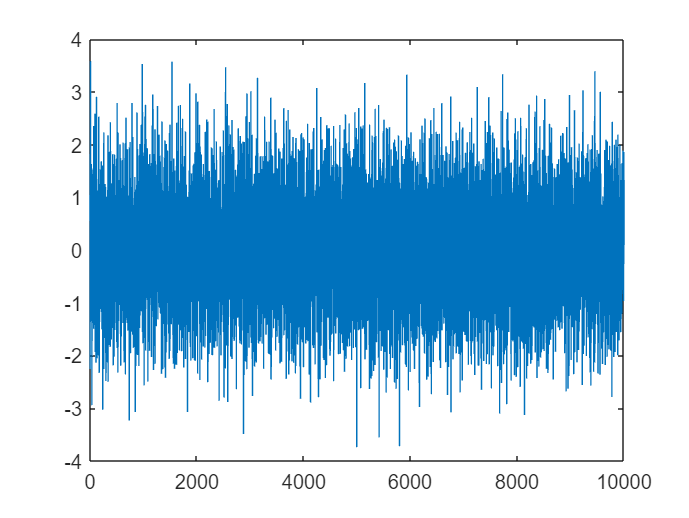

N = 10000; 
a = randn(N,1);
plot(a);

#### Cauchy eloszlás

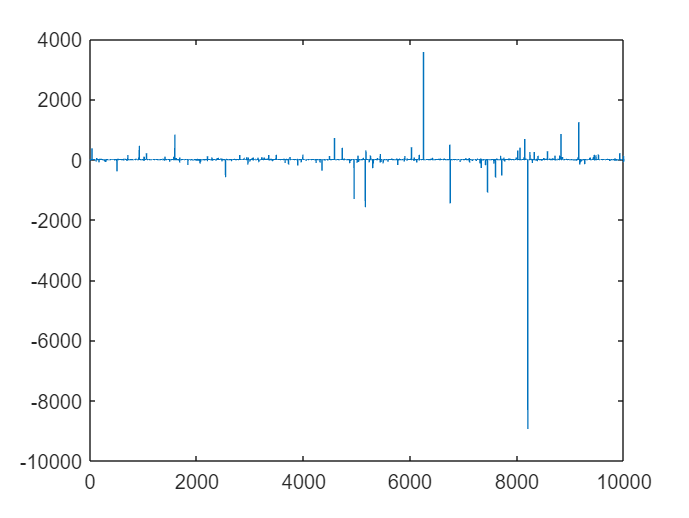

b = randn(N,1) ./ randn(N,1);
plot(b);

#### Sűrűségfüggvények

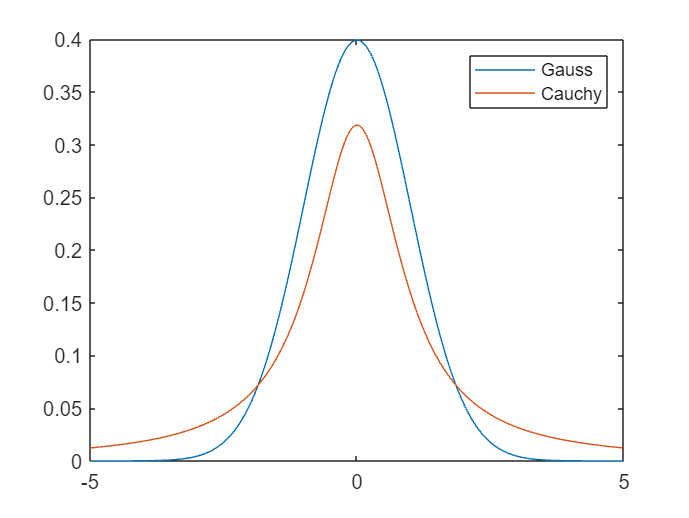

x = -5:0.01:5;
plot(x,normpdf(x));
hold on; 
plot(x,(1/pi)*1./(1+x.^2));
legend("Gauss","Cauchy")
hold off;

#### Nagy számok törvénye Gauss

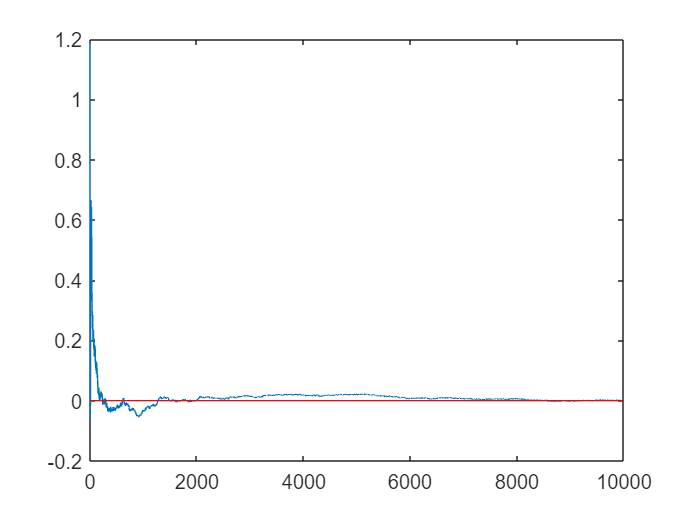

n = (1:N)'; %transzponálás
plot(cumsum(a)./n)
hold on 
plot(zeros(size(n)),"r");
hold off

#### Nagy számok törvénye Cauchy 

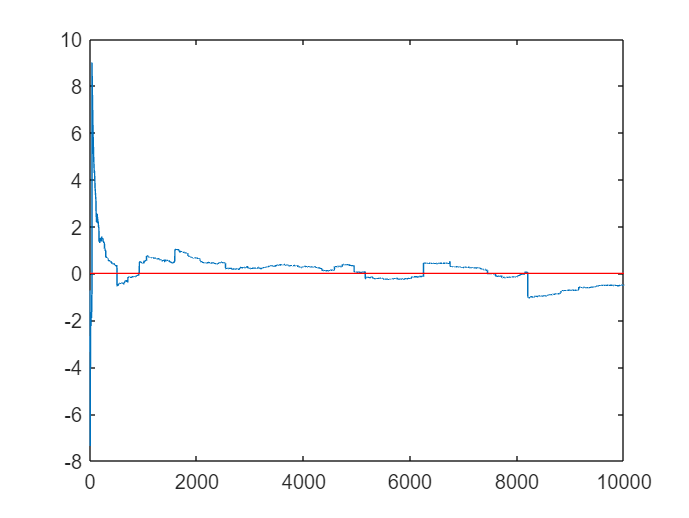

n = (1:N)'; %transzponálás
plot(cumsum(b)./n)
hold on 
plot(zeros(size(n)),"r");
hold off

#### T-eloszlás

sf =3

sf = 3

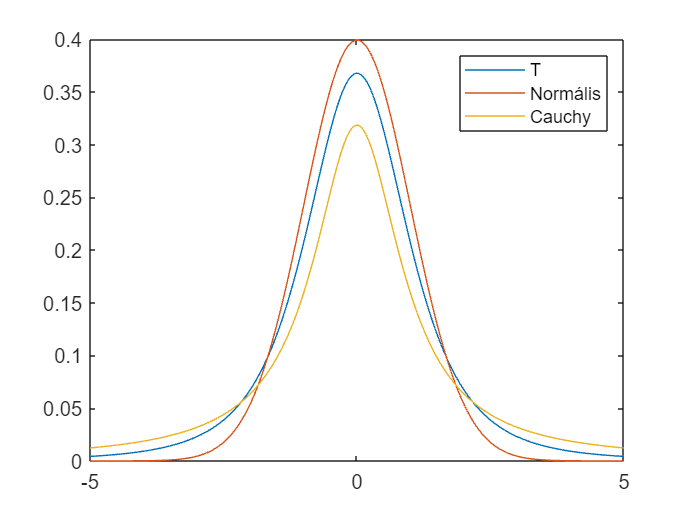

plot(x,tpdf(x,sf))
hold on;
plot(x,normpdf(x));
plot(x,(1/pi)*1./(1+x.^2));
hold off; 
legend("T","Normális","Cauchy")

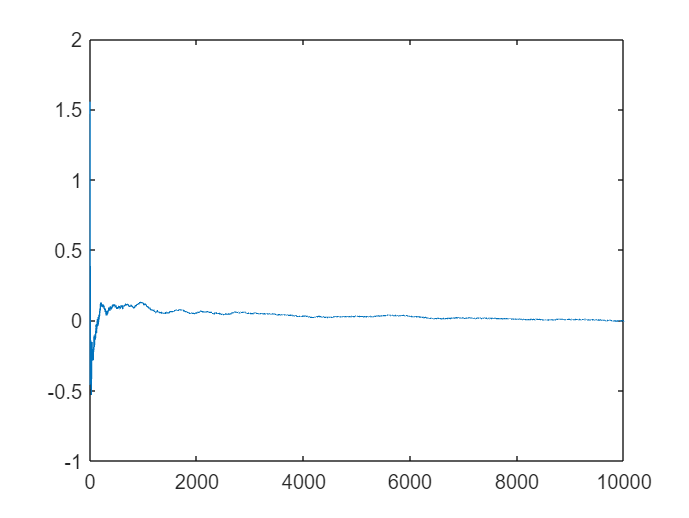

d = trnd(sf,N,1);
plot(cumsum(d)./n)